% Compare current injection tuning curves to cell attached tuning curves
% for superior and inferior cells

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

%THERE ARE MULTIPLE VERSIONS OF THE CUTOFF VALUES THAT YOU CAN CHOOSE. THE
%ORIGINAL ONE (cutoffValues.mat) TAKES THE MOST EXTREME DEPOLARIZED AND
%HYPERPOLARIZED EPOCHS. cutoffValues_lessHyperpolarized.mat TAKES LESS
%HYPERPOLARIZED EPOCHS FOR THE HYPERPOLARIZED VERSIONS (if they're
%available).
cutoffFname = 'cutoffValues.mat'; %choose which cutoff value file to use here

cutoffFilePath = ['C:\Users\mrsco\Box\Completed_Analysis\WholeCell\CurrentInjections\' cutoffFname];
load([cutoffFilePath]);

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name shosuld be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'CurrentClamp', 'PotassiumSpikes', '_ManyVms'};
cantHave_1 = [];
cantHave_2 = {'Cesium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upHPCurves = [];
upDPCurves = [];
upHPVms = [];
upDPVms = [];
upHPDSIs = [];
upDPDSIs = [];
upHPpreferredDirections = [];
upDPpreferredDirections = [];
upEpochNumsByCell = {};
upNames = {};
for i = 1:size(ups)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    Vms = loc.Analysis_Results.restingMembranePotentialByEpoch;
    cname = struct_i.cellID;
    
    %determine whether cutoff values have been set for this cell yet
    found = 0;
    for j = 1:size(cutoffValues, 1)
        if strcmp(cname, cutoffValues{j, 1})
            found = 1;
            cutoffs = cutoffValues{j, 2};
            break
        end
    end
    
    if ~found
        continue
    end
    
    upEpochNumsByCell(end + 1, 1) = {cname};
    hpEpochs = Vms>= cutoffs(1) & Vms <= cutoffs(2); %get hyperpolarazation epochs
    dpEpochs = Vms >= cutoffs(3) & Vms <= cutoffs(4); %get depolarization epochs
    
    upEpochNumsByCell(end, 2) = {loc.Analysis_Results.EpochNumbers(hpEpochs)};
    upEpochNumsByCell(end, 3) = {loc.Analysis_Results.orientationByEpoch(hpEpochs)};
    upEpochNumsByCell(end, 4) = {loc.Analysis_Results.EpochNumbers(dpEpochs)};
    upEpochNumsByCell(end, 5) = {loc.Analysis_Results.orientationByEpoch(dpEpochs)};
    
    %write down the direction of each epoch in each category
    hpDirections = loc.Analysis_Results.orientationByEpoch(hpEpochs);
    dpDirections = loc.Analysis_Results.orientationByEpoch(dpEpochs);
    
    %build a template response matrix. This is an nx3 matrix where n = the
    %number of directions probed in the stimulus. Column 1 is simply each direction
    %Column 2 is the sum of the total number of spikes across all epochs for the
    %corresponding direction. Column 3 is the number of epochs for that
    %direction. The average tuning curve is found by dividing column 2 by
    %column 3.
    allDirections = loc.Analysis_Results.Orientation;
    allDirections = sort(allDirections);
    responseMatrix = zeros(numel(allDirections), 3);
    responseMatrix(:, 1) = allDirections;
    
    hpResponseMatrix = responseMatrix;
    hpSpikeTimes = loc.Analysis_Results.allSpikeTimes(hpEpochs);
    for j = 1:numel(hpSpikeTimes)
        numSpikes = numel(hpSpikeTimes{j});
        direction = hpDirections(j);
        index = hpResponseMatrix(:, 1) == direction;
        hpResponseMatrix(index, 2:3) = [hpResponseMatrix(index, 2:3)] + [numSpikes, 1];
    end
    
    
    dpResponseMatrix = responseMatrix;
    dpSpikeTimes = loc.Analysis_Results.allSpikeTimes(dpEpochs);
    for j = 1:numel(dpSpikeTimes)
        numSpikes = numel(dpSpikeTimes{j});
        direction = dpDirections(j);
        index = dpResponseMatrix(:, 1) == direction;
        dpResponseMatrix(index, 2:3) = [dpResponseMatrix(index, 2:3)] + [numSpikes, 1];
    end
    
    %     if min(hpResponseMatrix(:, 3)) < 2 || min(dpResponseMatrix(:, 3)) < 2
    %         continue %skip this cell if there aren't at least 2 epochs in each direction for each condition
    %     end
    
    %find the mean tuning curves
    hpTuningCurve = (hpResponseMatrix(:, 2)./hpResponseMatrix(:, 3))';
    dpTuningCurve = (dpResponseMatrix(:, 2)./dpResponseMatrix(:, 3))';
    
    %calculate the DSI and vector
    [hpDSI, hpVector] = calculateDSI(allDirections, hpTuningCurve);
    [dpDSI, dpVector] = calculateDSI(allDirections, dpTuningCurve);
    
    %write down the information
    upHPCurves(end+1, :) = hpTuningCurve;
    upDPCurves(end+1, :) = dpTuningCurve;
    upHPVms(end + 1, :) = mean(Vms(hpEpochs));
    upDPVms(end + 1, :) = mean(Vms(dpEpochs));
    upHPDSIs(end+1, 1) = hpDSI;
    upDPDSIs(end+1, 1) = dpDSI;
    upHPpreferredDirections(end+1, 1) = mod(hpVector(1), 360);
    upDPpreferredDirections(end+1, 1) = mod(dpVector(1), 360);
    upNames{end + 1} = struct_i.cellID;
end

downHPCurves = [];
downDPCurves = [];
downHPVms = [];
downDPVms = [];
downHPDSIs = [];
downDPDSIs = [];
downHPpreferredDirections = [];
downDPpreferredDirections = [];
downEpochNumsByCell = {};
downNames = {};
for i = 1:size(downs)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    Vms = loc.Analysis_Results.restingMembranePotentialByEpoch;
    cname = struct_i.cellID;
    
    %determine whether cutoff values have been set for this cell yet
    found = 0;
    for j = 1:size(cutoffValues, 1)
        if strcmp(cname, cutoffValues{j, 1})
            found = 1;
            cutoffs = cutoffValues{j, 2};
            break
        end
    end
    
    if ~found
        continue
    end
    
    downEpochNumsByCell(end + 1, 1) = {cname};
    hpEpochs = Vms>= cutoffs(1) & Vms <= cutoffs(2); %get hyperpolarazation epochs
    dpEpochs = Vms >= cutoffs(3) & Vms <= cutoffs(4); %get depolarization epochs
    
    downEpochNumsByCell(end, 2) = {loc.Analysis_Results.EpochNumbers(hpEpochs)};
    downEpochNumsByCell(end, 3) = {loc.Analysis_Results.orientationByEpoch(hpEpochs)};
    downEpochNumsByCell(end, 4) = {loc.Analysis_Results.EpochNumbers(dpEpochs)};
    downEpochNumsByCell(end, 5) = {loc.Analysis_Results.orientationByEpoch(dpEpochs)};
    
    
    hpDirections = loc.Analysis_Results.orientationByEpoch(hpEpochs);
    dpDirections = loc.Analysis_Results.orientationByEpoch(dpEpochs);
    
    allDirections = loc.Analysis_Results.Orientation;
    allDirections = sort(allDirections);
    responseMatrix = zeros(numel(allDirections), 3);
    responseMatrix(:, 1) = allDirections;
    
    hpResponseMatrix = responseMatrix;
    hpSpikeTimes = loc.Analysis_Results.allSpikeTimes(hpEpochs);
    for j = 1:numel(hpSpikeTimes)
        numSpikes = numel(hpSpikeTimes{j});
        direction = hpDirections(j);
        index = hpResponseMatrix(:, 1) == direction;
        hpResponseMatrix(index, 2:3) = [hpResponseMatrix(index, 2:3)] + [numSpikes, 1];
    end
    
    
    dpResponseMatrix = responseMatrix;
    dpSpikeTimes = loc.Analysis_Results.allSpikeTimes(dpEpochs);
    for j = 1:numel(dpSpikeTimes)
        numSpikes = numel(dpSpikeTimes{j});
        direction = dpDirections(j);
        index = dpResponseMatrix(:, 1) == direction;
        dpResponseMatrix(index, 2:3) = [dpResponseMatrix(index, 2:3)] + [numSpikes, 1];
    end
    
    %     if min(hpResponseMatrix(:, 3)) < 2 || min(dpResponseMatrix(:, 3)) < 2
    %         continue %skip this cell if there aren't at least 2 epochs in each direction for each condition
    %     end
    
    hpTuningCurve = (hpResponseMatrix(:, 2)./hpResponseMatrix(:, 3))';
    dpTuningCurve = (dpResponseMatrix(:, 2)./dpResponseMatrix(:, 3))';
    
    [hpDSI, hpVector] = calculateDSI(allDirections, hpTuningCurve);
    [dpDSI, dpVector] = calculateDSI(allDirections, dpTuningCurve);
    
    downHPCurves(end+1, :) = hpTuningCurve;
    downDPCurves(end+1, :) = dpTuningCurve;
    downHPVms(end + 1, :) = mean(Vms(hpEpochs));
    downDPVms(end + 1, :) = mean(Vms(dpEpochs));
    downHPDSIs(end+1, 1) = hpDSI;
    downDPDSIs(end+1, 1) = dpDSI;
    downHPpreferredDirections(end+1, 1) = mod(hpVector(1), 360);
    downDPpreferredDirections(end+1, 1) = mod(dpVector(1), 360);
    downNames{end + 1} = struct_i.cellID;
end


%calculate noramlized tuning curves:

stepSize = 0.25; %step size for interpolation in degrees
interpolationMethod = 'linear';
xvals = [allDirections, 360];
interpolationPoints = [0:stepSize:360]; %in degrees

upNormalizedHPCurves = zeros(size(upHPCurves, 1), numel(allDirections)+1);
upNormalizedDPCurves = zeros(size(upDPCurves, 1), numel(allDirections)+1);

upHP_CW = zeros(size(upHPCurves, 1), floor(numel(interpolationPoints)/2));
upHP_CCW = zeros(size(upHPCurves, 1), floor(numel(interpolationPoints)/2));
upDP_CW = zeros(size(upHPCurves, 1), floor(numel(interpolationPoints)/2));
upDP_CCW = zeros(size(upHPCurves, 1), floor(numel(interpolationPoints)/2));
for i = 1:size(upHPCurves, 1)
    hpCurve_i = upHPCurves(i, :);
    hpCircularCurve_i = [hpCurve_i, hpCurve_i(1)];
    hpPD = upHPpreferredDirections(i);
    hpPDFR = interp1(xvals, hpCircularCurve_i, hpPD, interpolationMethod);
    
    normalizedHPCurve = hpCircularCurve_i./hpPDFR;
    upNormalizedHPCurves(i, :) = normalizedHPCurve;
    
    fullHPCurve = interp1(xvals, normalizedHPCurve, interpolationPoints, interpolationMethod);
    doubledHPCurve = [fullHPCurve, fullHPCurve];
    [~, currentHPIndex] = min(abs(interpolationPoints-hpPD));
    counterClockwiseHPCurve = doubledHPCurve(currentHPIndex:end);
    clockwiseHPCurve = fliplr(doubledHPCurve(1:currentHPIndex+numel(fullHPCurve)));
    upHP_CCW(i, :) = counterClockwiseHPCurve(1:180/stepSize);
    upHP_CW(i, :) = clockwiseHPCurve(1:180/stepSize);
    
    dpCurve_i = upDPCurves(i, :);
    dpCircularCurve_i = [dpCurve_i, dpCurve_i(1)];
    dpPD = upDPpreferredDirections(i);
    dpPDFR = interp1(xvals, dpCircularCurve_i, dpPD, interpolationMethod);
    
    normalizedDPCurve = dpCircularCurve_i./dpPDFR;
    upNormalizedDPCurves(i, :) = normalizedDPCurve;
    
    fullDPCurve = interp1(xvals, normalizedDPCurve, interpolationPoints, interpolationMethod);
    doubledDPCurve = [fullDPCurve, fullDPCurve];
    [~, currentDPIndex] = min(abs(interpolationPoints-dpPD));
    counterClockwiseDPCurve = doubledDPCurve(currentDPIndex:end);
    clockwiseDPCurve = fliplr(doubledDPCurve(1:currentDPIndex+numel(fullDPCurve)));
    upDP_CCW(i, :) = counterClockwiseDPCurve(1:180/stepSize);
    upDP_CW(i, :) = clockwiseDPCurve(1:180/stepSize);
end

upHP_CWAvg = mean(upHP_CW);
upHP_CWAvgSE = std(upHP_CW)/sqrt(size(upHPCurves, 1));
upHP_CCWAvg = mean(upHP_CCW);
upHP_CCWAvgSE = std(upHP_CCW)/sqrt(size(upHPCurves, 1));

upDP_CWAvg = mean(upDP_CW);
upDP_CWAvgSE = std(upDP_CW)/sqrt(size(upDPCurves, 1));
upDP_CCWAvg = mean(upDP_CCW);
upDP_CCWAvgSE = std(upDP_CCW)/sqrt(size(upDPCurves, 1));


downNormalizedHPCurves = zeros(size(downHPCurves, 1), numel(allDirections)+1);
downNormalizedDPCurves = zeros(size(downDPCurves, 1), numel(allDirections)+1);

downHP_CW = zeros(size(downHPCurves, 1), floor(numel(interpolationPoints)/2));
downHP_CCW = zeros(size(downHPCurves, 1), floor(numel(interpolationPoints)/2));
downDP_CW = zeros(size(downHPCurves, 1), floor(numel(interpolationPoints)/2));
downDP_CCW = zeros(size(downHPCurves, 1), floor(numel(interpolationPoints)/2));
for i = 1:size(downHPCurves, 1)
    hpCurve_i = downHPCurves(i, :);
    hpCircularCurve_i = [hpCurve_i, hpCurve_i(1)];
    hpPD = downHPpreferredDirections(i);
    hpPDFR = interp1(xvals, hpCircularCurve_i, hpPD, interpolationMethod);
    
    normalizedHPCurve = hpCircularCurve_i./hpPDFR;
    downNormalizedHPCurves(i, :) = normalizedHPCurve;
    
    fullHPCurve = interp1(xvals, normalizedHPCurve, interpolationPoints, interpolationMethod);
    doubledHPCurve = [fullHPCurve, fullHPCurve];
    [~, currentHPIndex] = min(abs(interpolationPoints-hpPD));
    counterClockwiseHPCurve = doubledHPCurve(currentHPIndex:end);
    clockwiseHPCurve = fliplr(doubledHPCurve(1:currentHPIndex+numel(fullHPCurve)));
    downHP_CCW(i, :) = counterClockwiseHPCurve(1:180/stepSize);
    downHP_CW(i, :) = clockwiseHPCurve(1:180/stepSize);
    
    dpCurve_i = downDPCurves(i, :);
    dpCircularCurve_i = [dpCurve_i, dpCurve_i(1)];
    dpPD = downDPpreferredDirections(i);
    dpPDFR = interp1(xvals, dpCircularCurve_i, dpPD, interpolationMethod);
    
    normalizedDPCurve = dpCircularCurve_i./dpPDFR;
    downNormalizedDPCurves(i, :) = normalizedDPCurve;
    
    fullDPCurve = interp1(xvals, normalizedDPCurve, interpolationPoints, interpolationMethod);
    doubledDPCurve = [fullDPCurve, fullDPCurve];
    [~, currentDPIndex] = min(abs(interpolationPoints-dpPD));
    counterClockwiseDPCurve = doubledDPCurve(currentDPIndex:end);
    clockwiseDPCurve = fliplr(doubledDPCurve(1:currentDPIndex+numel(fullDPCurve)));
    downDP_CCW(i, :) = counterClockwiseDPCurve(1:180/stepSize);
    downDP_CW(i, :) = clockwiseDPCurve(1:180/stepSize);
end
downHP_CWAvg = mean(downHP_CW);
downHP_CWAvgSE = std(downHP_CW)/sqrt(size(downHPCurves, 1));
downHP_CCWAvg = mean(downHP_CCW);
downHP_CCWAvgSE = std(downHP_CCW)/sqrt(size(downHPCurves, 1));

downDP_CWAvg = mean(downDP_CW);
downDP_CWAvgSE = std(downDP_CW)/sqrt(size(downDPCurves, 1));
downDP_CCWAvg = mean(downDP_CCW);
downDP_CCWAvgSE = std(downDP_CCW)/sqrt(size(downDPCurves, 1));

%calculat normed tuning curve areas
upNormalizedHPAreas = trapz([allDirections, 360], upNormalizedHPCurves, 2)./360;
upNormalizedDPAreas = trapz([allDirections, 360], upNormalizedDPCurves, 2)./360;
downNormalizedHPAreas = trapz([allDirections, 360], downNormalizedHPCurves, 2)./360;
downNormalizedDPAreas = trapz([allDirections, 360], downNormalizedDPCurves, 2)./360;



## Repeat for spikes

interpolationMethod = 'linear';

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ff'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

allOrientations = [0:45:315];
upVals = zeros(0, numel(allOrientations));
upValsNormalizedToPD = zeros(0, numel(allOrientations));
downVals = zeros(0, numel(allOrientations));
downValsNormalizedToPD = zeros(0, numel(allOrientations));
upPDs = [];
downPDs = [];
upDSIs = [];
downDSIs = [];
indexer = 0;
%grab data for up cells
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    indexer = indexer + 1;
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    for j = 1:numel(orientations)
        o_j = orientations(j);
        upVals(indexer, allOrientations == o_j) = spikes(j);
    end
    circularSpikes = [upVals(indexer, :), upVals(indexer, 1)];
    pd = mod(loc.Analysis_Results.PreferredDirection, 360);
    upPDs = [upPDs; pd];
    pdFR = interp1([allOrientations, 360], circularSpikes, pd, interpolationMethod);
    upValsNormalizedToPD = [upValsNormalizedToPD; upVals(indexer, :)./pdFR];
    upDSIs = [upDSIs; loc.Analysis_Results.DSI];
end

indexer = 0;
%grab data for down cells
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass, a2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    indexer = indexer + 1;
    
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    for j = 1:numel(orientations)
        o_j = orientations(j);
        downVals(indexer, allOrientations == o_j) = spikes(j);
    end
    circularSpikes = [downVals(indexer, :), downVals(indexer, 1)];
    pd = mod(loc.Analysis_Results.PreferredDirection, 360);
    downPDs = [downPDs; pd];
    pdFR = interp1([allOrientations, 360], circularSpikes, pd, interpolationMethod);
    downValsNormalizedToPD = [downValsNormalizedToPD; downVals(indexer, :)./pdFR];
    downDSIs = [downDSIs; loc.Analysis_Results.DSI];
end
upAreas = [];
upNormedAreas = [];
for  i = 1:size(upVals, 1)
    upAreas = [upAreas trapz([allOrientations 360], [upVals(i, :), upVals(i, 1)])/360];
    upNormedAreas = [upNormedAreas trapz([allOrientations 360], [upValsNormalizedToPD(i, :), upValsNormalizedToPD(i, 1)])/360];
end

downAreas = [];
downNormedAreas = [];
for  i = 1:size(downVals, 1)
    downAreas = [downAreas trapz([allOrientations 360], [downVals(i, :), downVals(i, 1)])/360];
    downNormedAreas = [downNormedAreas trapz([allOrientations 360], [downValsNormalizedToPD(i, :), downValsNormalizedToPD(i, 1)])/360];
end


upCW = zeros(size(upVals, 1), floor(numel(interpolationPoints)/2));
upCCW = zeros(size(upVals, 1), floor(numel(interpolationPoints)/2));
for i = 1:size(upVals, 1)
    vals = upValsNormalizedToPD(i, :);
    fullTuningCurve = interp1(xvals, [vals, vals(1)], interpolationPoints, interpolationMethod);
    doubledCurve = [fullTuningCurve, fullTuningCurve];
    pd = upPDs(i);
    [~, currentIndex] = min(abs(interpolationPoints-pd));
    counterClockwiseCurve = doubledCurve(currentIndex:end);
    clockwiseCurve = fliplr(doubledCurve(1:currentIndex+numel(fullTuningCurve)));
    upCCW(i, :) = counterClockwiseCurve(1:180/stepSize);
    upCW(i, :) = clockwiseCurve(1:180/stepSize);
    
end
upCWAvg = mean(upCW);
upCWAvgSE = std(upCW)/sqrt(size(upVals, 1));
upCCWAvg = mean(upCCW);
upCCWAvgSE = std(upCCW)/sqrt(size(upVals, 1));

downCW = zeros(size(downVals, 1), floor(numel(interpolationPoints)/2));
downCCW = zeros(size(downVals, 1), floor(numel(interpolationPoints)/2));
for i = 1:size(downVals, 1)
    vals = downValsNormalizedToPD(i, :);
    fullTuningCurve = interp1(xvals, [vals, vals(1)], interpolationPoints, interpolationMethod);
    doubledCurve = [fullTuningCurve, fullTuningCurve];
    pd = downPDs(i);
    [~, currentIndex] = min(abs(interpolationPoints-pd));
    counterClockwiseCurve = doubledCurve(currentIndex:end);
    clockwiseCurve = fliplr(doubledCurve(1:currentIndex+numel(fullTuningCurve)));
    downCCW(i, :) = counterClockwiseCurve(1:180/stepSize);
    downCW(i, :) = clockwiseCurve(1:180/stepSize);
end
downCWAvg = mean(downCW);
downCWAvgSE = std(downCW)/sqrt(size(downVals, 1));
downCCWAvg = mean(downCCW);
downCCWAvgSE = std(downCCW)/sqrt(size(downVals, 1));


## Mean Normalized Tuning Curves

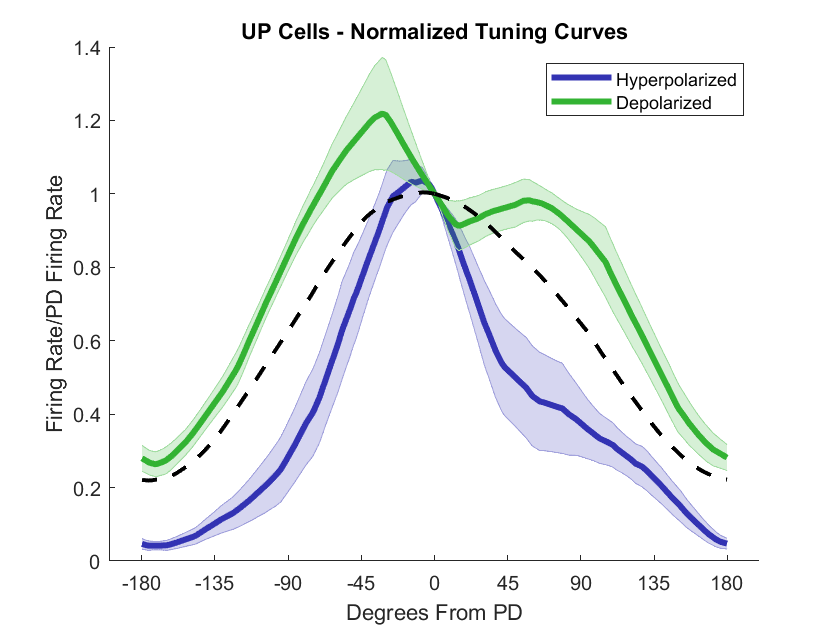

figure
title('UP Cells - Normalized Tuning Curves')
hold on
shadedErrorBar([0:stepSize:180-stepSize], upHP_CWAvg, upHP_CWAvgSE, 'lineprops', {'linewidth', 3, 'Color', [0.2, 0.2, 0.7]});
shadedErrorBar([0:stepSize:180-stepSize], upDP_CWAvg, upDP_CWAvgSE, 'lineprops', {'linewidth', 3, 'Color', [0.2, 0.7, 0.2]});
shadedErrorBar([0:-stepSize:-180+stepSize], upHP_CCWAvg, upHP_CCWAvgSE, 'lineprops', {'linewidth', 3, 'Color', [0.2, 0.2, 0.7]});
shadedErrorBar([0:-stepSize:-180+stepSize], upDP_CCWAvg, upDP_CCWAvgSE, 'lineprops', {'linewidth', 3, 'Color', [0.2, 0.7, 0.2]});
plot([0:0.25:179.75], upCWAvg, '--k', 'linewidth', 2)
plot([0:-0.25:-179.75], upCCWAvg, '--k', 'linewidth', 2)
xticks([-180:45:180])
legend('Hyperpolarized', 'Depolarized')
xlabel('Degrees From PD')
ylabel('Firing Rate/PD Firing Rate')

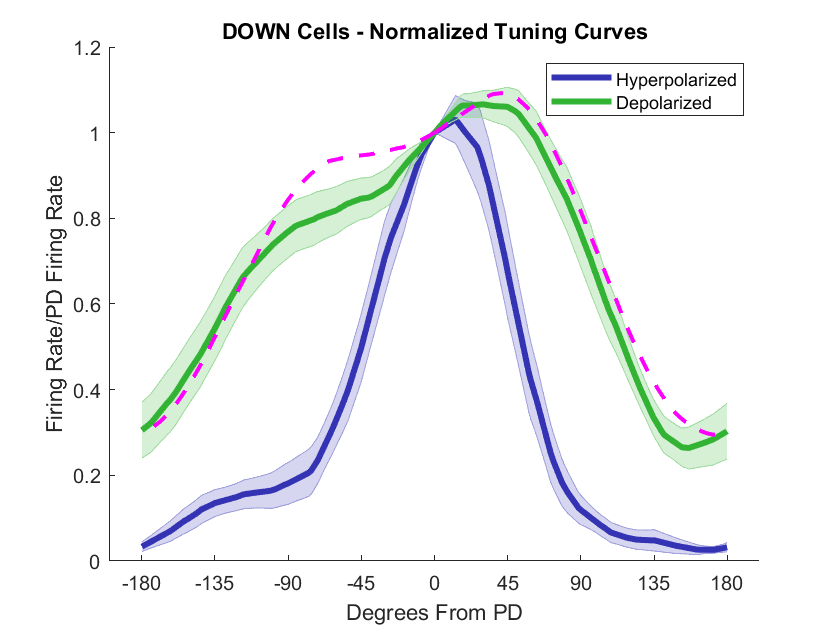


figure
title('DOWN Cells - Normalized Tuning Curves')
hold on
shadedErrorBar([0:stepSize:180-stepSize], downHP_CWAvg, downHP_CWAvgSE, 'lineprops', {'linewidth', 3, 'Color', [0.2, 0.2, 0.7]});
shadedErrorBar([0:stepSize:180-stepSize], downDP_CWAvg, downDP_CWAvgSE, 'lineprops', {'linewidth', 3, 'Color', [0.2, 0.7, 0.2]});
shadedErrorBar([0:-stepSize:-180+stepSize], downHP_CCWAvg, downHP_CCWAvgSE, 'lineprops', {'linewidth', 3, 'Color', [0.2, 0.2, 0.7]});
shadedErrorBar([0:-stepSize:-180+stepSize], downDP_CCWAvg, downDP_CCWAvgSE, 'lineprops', {'linewidth', 3, 'Color', [0.2, 0.7, 0.2]});
plot([0:0.25:179.75], downCWAvg, '--m', 'linewidth', 2)
plot([0:-0.25:-179.75], downCCWAvg, '--m', 'linewidth', 2)
xticks([-180:45:180])
legend('Hyperpolarized', 'Depolarized')
xlabel('Degrees From PD')
ylabel('Firing Rate/PD Firing Rate')

## Normalized Areas

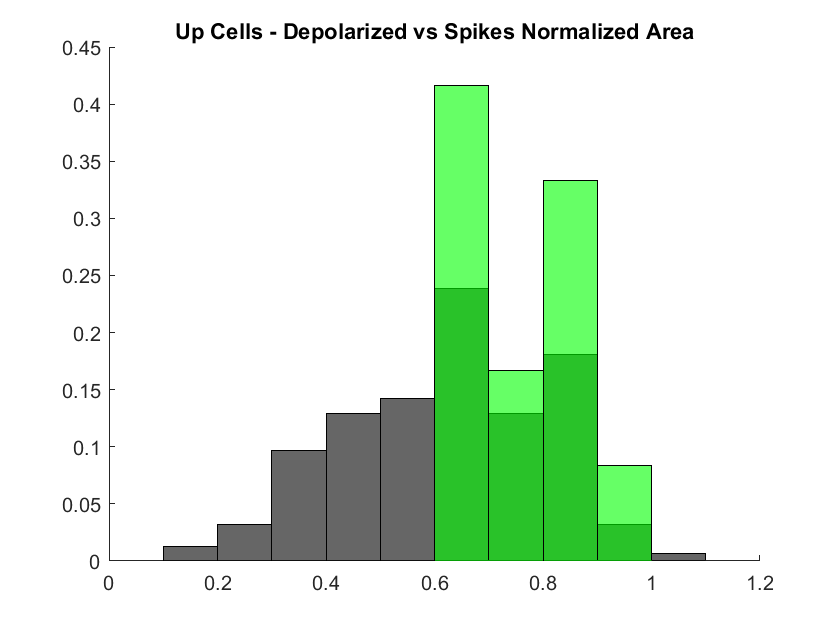


figure()
title('Up Cells - Depolarized vs Spikes Normalized Area')
hold on
h1 = histogram(upNormedAreas, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(upNormalizedDPAreas, 'FaceColor', 'g', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
xlim([0, 1.2])


p = ranksum(upNormedAreas, upNormalizedDPAreas)

p = 0.0062

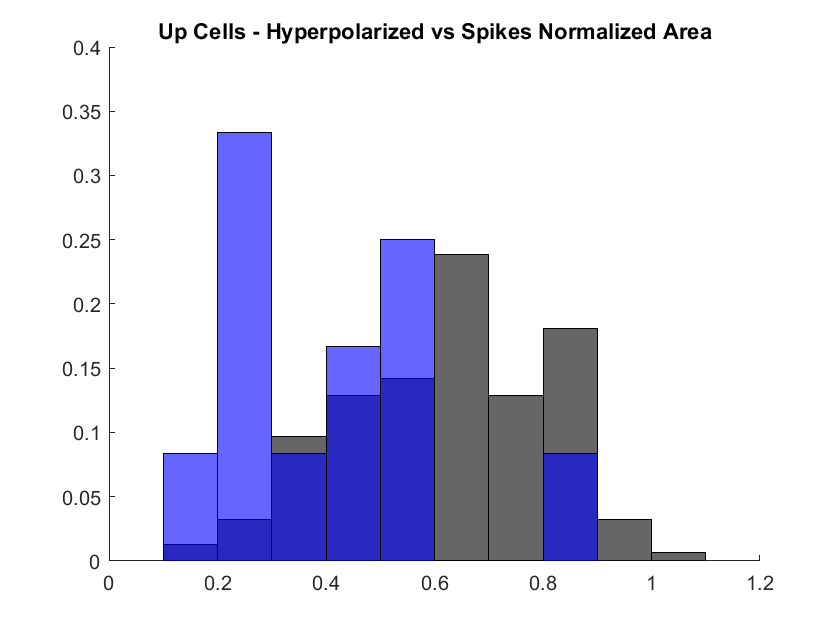


figure()
title('Up Cells - Hyperpolarized vs Spikes Normalized Area')
hold on
h1 = histogram(upNormedAreas, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(upNormalizedHPAreas, 'FaceColor', 'b', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
xlim([0, 1.2])
ylim([0, 0.4])


p = ranksum(upNormedAreas, upNormalizedHPAreas)

p = 6.4622e-04

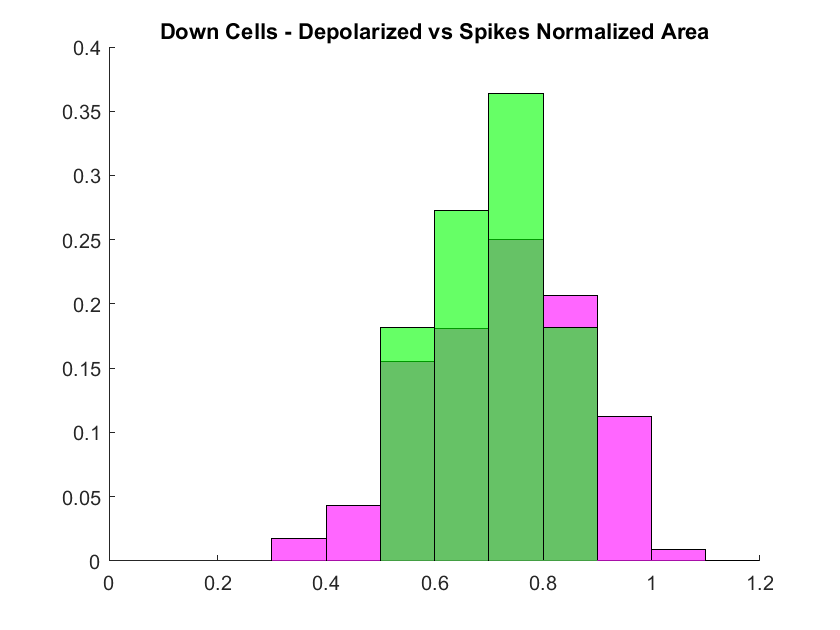


figure()
title('Down Cells - Depolarized vs Spikes Normalized Area')
hold on
h1 = histogram(downNormedAreas, 'FaceColor', 'm', 'Normalization', 'probability');
h2 = histogram(downNormalizedDPAreas, 'FaceColor', 'g', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
xlim([0, 1.2])


p = ranksum(downNormedAreas, downNormalizedDPAreas)

p = 0.5287

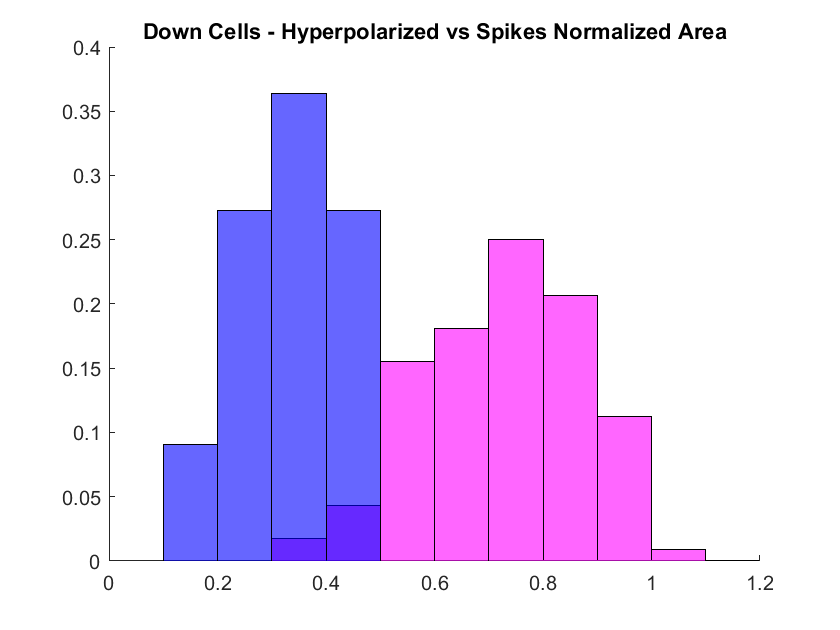


figure()
title('Down Cells - Hyperpolarized vs Spikes Normalized Area')
hold on
h1 = histogram(downNormedAreas, 'FaceColor', 'm', 'Normalization', 'probability');
h2 = histogram(downNormalizedHPAreas, 'FaceColor', 'b', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
xlim([0, 1.2])


p = ranksum(downNormedAreas, downNormalizedHPAreas)

p = 8.6534e-08

## DSI

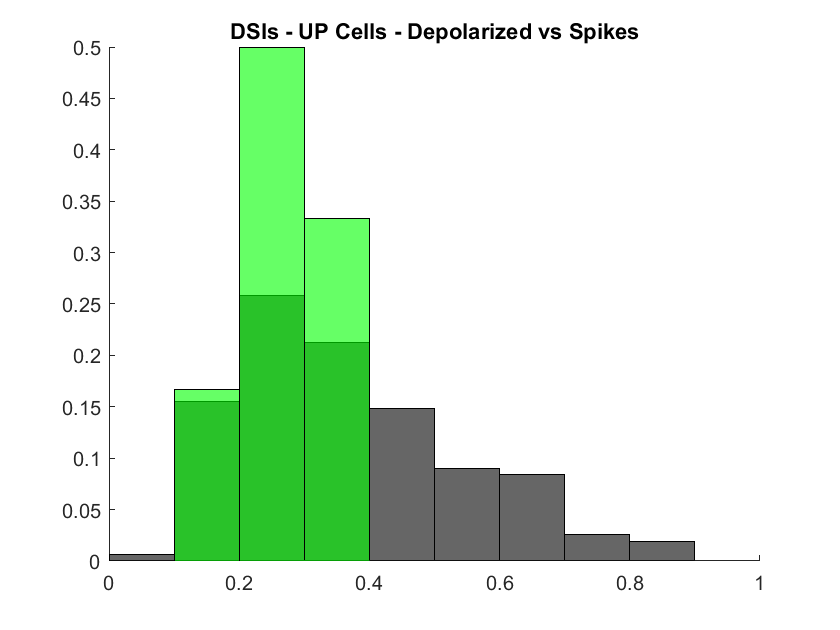

figure
title('DSIs - UP Cells - Depolarized vs Spikes')
hold on
h1 = histogram(upDSIs, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(upDPDSIs, 'FaceColor', 'g', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
xlim([0, 1])


p = ranksum(upDSIs, upDPDSIs)

p = 0.0844

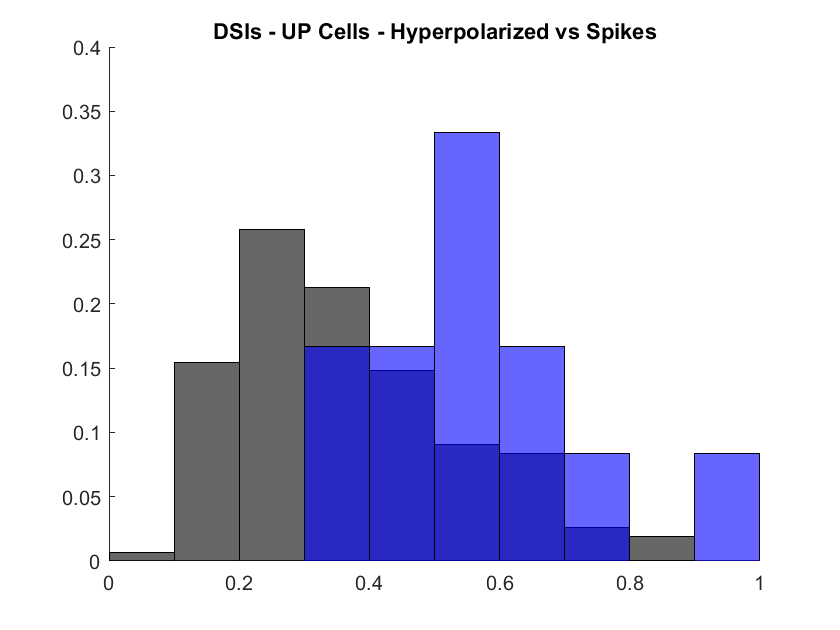


figure
title('DSIs - UP Cells - Hyperpolarized vs Spikes')
hold on
h1 = histogram(upDSIs, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(upHPDSIs, 'FaceColor', 'b', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
xlim([0, 1])
ylim([0, 0.4])


p = ranksum(upDSIs, upHPDSIs)

p = 3.9775e-04

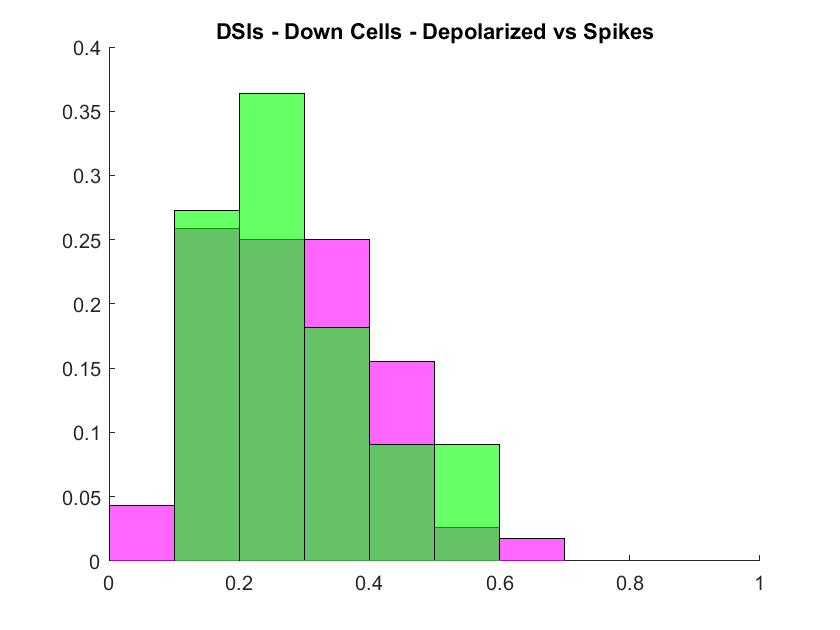


figure
title('DSIs - Down Cells - Depolarized vs Spikes')
hold on
h1 = histogram(downDSIs, 'FaceColor', 'm', 'Normalization', 'probability');
h2 = histogram(downDPDSIs, 'FaceColor', 'g', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
xlim([0, 1])


p = ranksum(downDSIs, downDPDSIs)

p = 0.7938

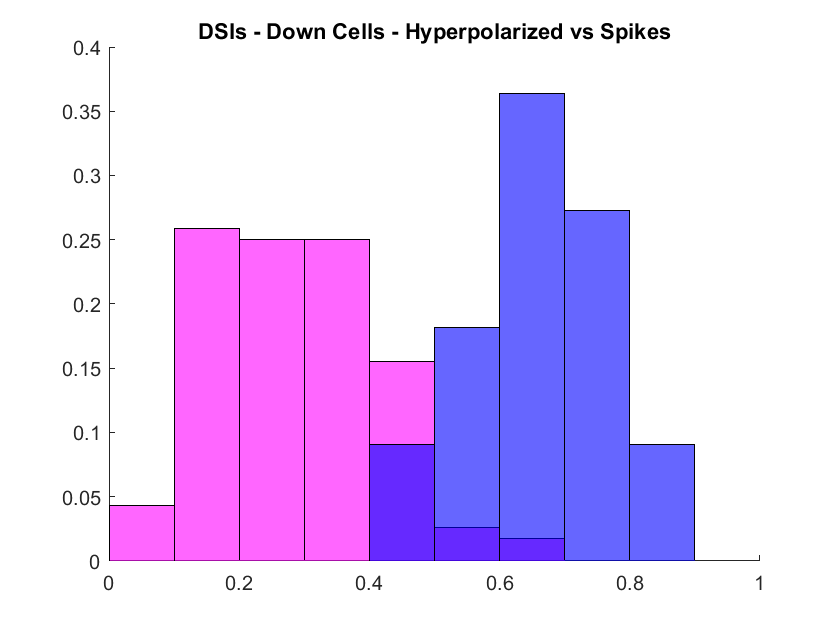


figure
title('DSIs - Down Cells - Hyperpolarized vs Spikes')
hold on
h1 = histogram(downDSIs, 'FaceColor', 'm', 'Normalization', 'probability');
h2 = histogram(downHPDSIs, 'FaceColor', 'b', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
xlim([0, 1])


p = ranksum(downDSIs, downHPDSIs)

p = 1.5926e-07

## Tuning Curve Areas

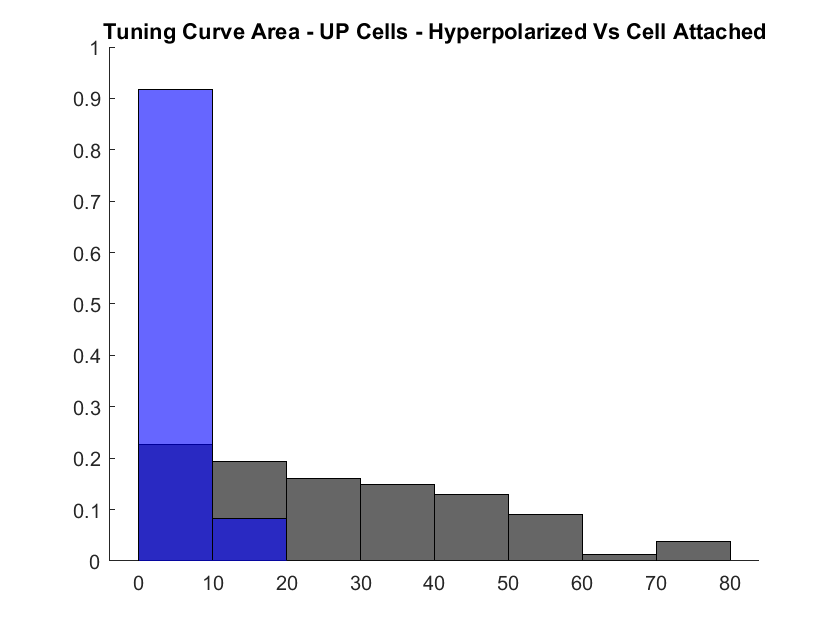

sortedOrientations = [sort(orientations), 360];
upHPAreas = trapz(sortedOrientations, [upHPCurves, upHPCurves(:, 1)], 2)./360;
upDPAreas = trapz(sortedOrientations, [upDPCurves, upDPCurves(:, 1)], 2)./360;
upSpikeAreas = trapz(sortedOrientations, [upVals, upVals(:, 1)], 2)./360;

downHPAreas = trapz(sortedOrientations, [downHPCurves, downHPCurves(:, 1)], 2)./360;
downDPAreas = trapz(sortedOrientations, [downDPCurves, downDPCurves(:, 1)], 2)./360;
downSpikeAreas = trapz(sortedOrientations, [downVals, downVals(:, 1)], 2)./360;

figure
title('Tuning Curve Area - UP Cells - Hyperpolarized Vs Cell Attached')
hold on
h1 = histogram(upSpikeAreas, 'FaceColor', 'k', 'normalization', 'probability');
h2 = histogram(upHPAreas, 'FaceColor', 'b', 'normalization', 'probability');
h2.BinWidth = h1.BinWidth;


p = ranksum(upSpikeAreas, upHPAreas)

p = 8.7349e-06

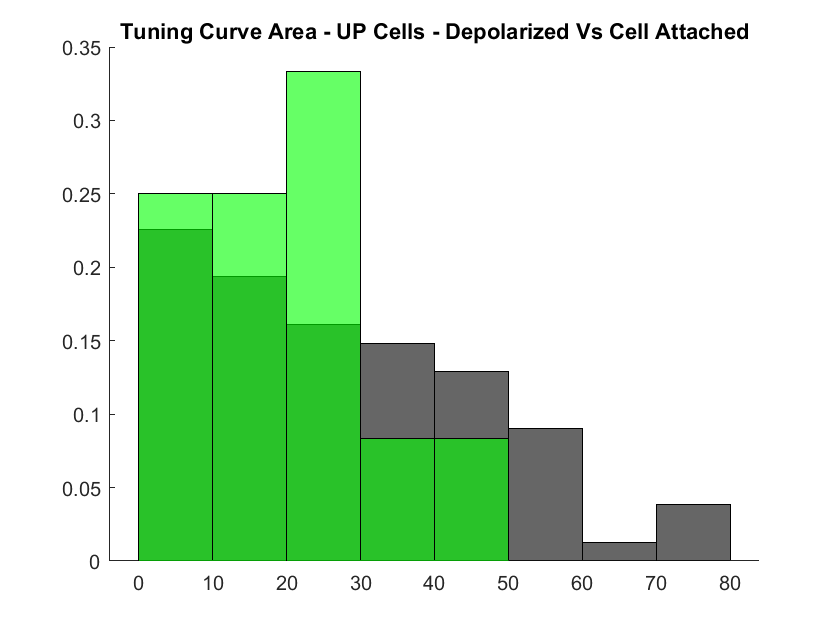


figure
title('Tuning Curve Area - UP Cells - Depolarized Vs Cell Attached')
hold on
h1 = histogram(upSpikeAreas, 'FaceColor', 'k', 'normalization', 'probability');
h2 = histogram(upDPAreas, 'FaceColor', 'g', 'normalization', 'probability');
h2.BinWidth = h1.BinWidth;

p = ranksum(upSpikeAreas, upDPAreas)

p = 0.3574

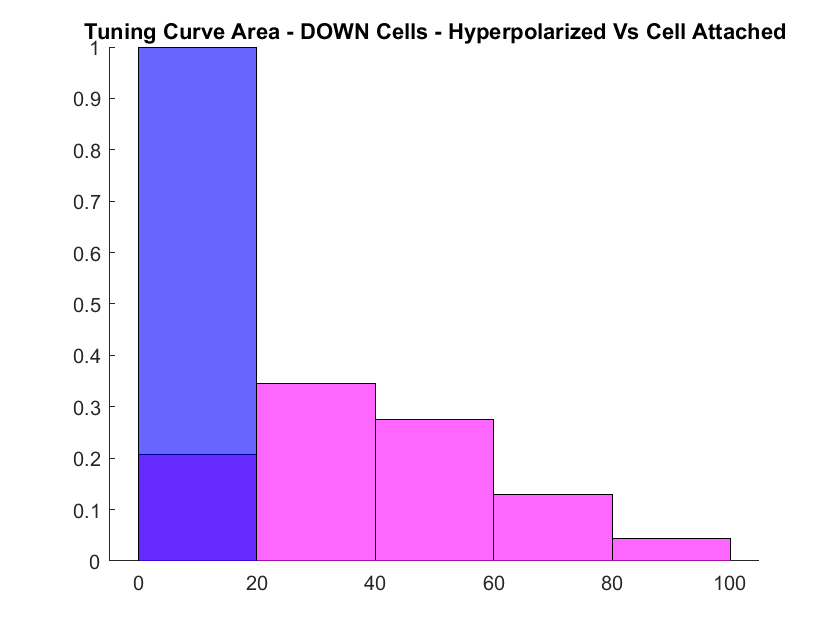



figure
title('Tuning Curve Area - DOWN Cells - Hyperpolarized Vs Cell Attached')
hold on
h1 = histogram(downSpikeAreas, 'FaceColor', 'm', 'normalization', 'probability');
h2 = histogram(downHPAreas, 'FaceColor', 'b', 'normalization', 'probability');
h2.BinWidth = h1.BinWidth;


p = ranksum(downSpikeAreas, downHPAreas)

p = 9.4411e-07

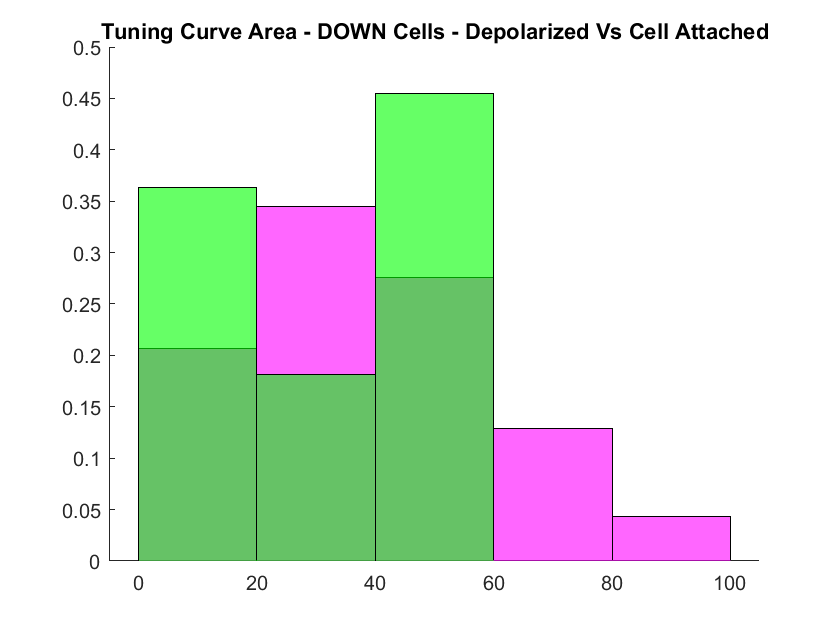


figure
title('Tuning Curve Area - DOWN Cells - Depolarized Vs Cell Attached')
hold on
h1 = histogram(downSpikeAreas, 'FaceColor', 'm', 'normalization', 'probability');
h2 = histogram(downDPAreas, 'FaceColor', 'g', 'normalization', 'probability');
h2.BinWidth = h1.BinWidth;

p = ranksum(downSpikeAreas, downDPAreas)

p = 0.3392